# Classify Query Data

This example shows how to classify query data by:

- Growing a *K*d-tree

- Conducting a *k* nearest neighbor search using the grown tree.

- Assigning each query point the class with the highest representation among their respective nearest neighbors.

Classify a new point based on the last two columns of the Fisher iris data. Using only the last two columns makes it easier to plot.

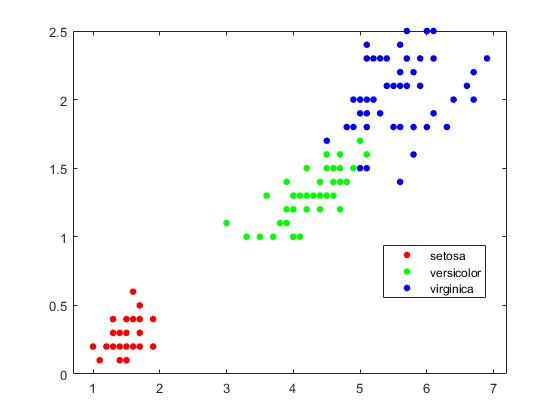

load fisheriris
x = meas(:,3:4);
gscatter(x(:,1),x(:,2),species)
legend('Location','best')

Plot the new point.

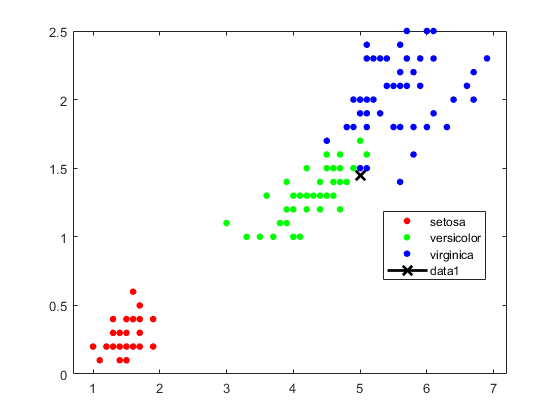

newpoint = [5 1.45];
line(newpoint(1),newpoint(2),'marker','x','color','k',...
   'markersize',10,'linewidth',2)

Mdl = KDTreeSearcher(x)

Mdl =   KDTreeSearcher - 属性:

       BucketSize: 50
         Distance: 'euclidean'
    DistParameter: []
                X: [150×2 double]


`Mdl` is a `KDTreeSearcher` model. By default, the distance metric it uses to search for neighbors is Euclidean distance.

Find the 10 sample points closest to the new point.Prepare a *K*d-tree neighbor searcher model.

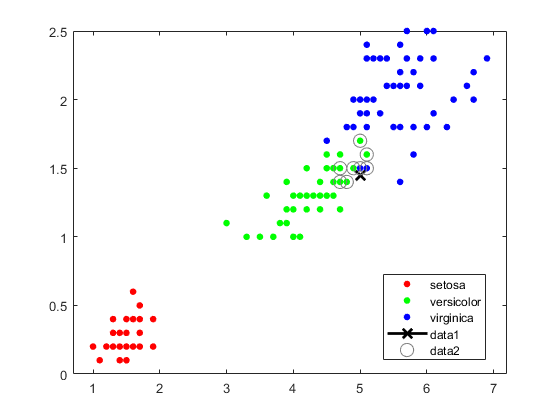


[n,d] = knnsearch(Mdl,newpoint,'k',10);
line(x(n,1),x(n,2),'color',[.5 .5 .5],'marker','o',...
    'linestyle','none','markersize',10)

It appears that `knnsearch` has found only the nearest eight neighbors. In fact, this particular dataset contains duplicate values.

x(n,:)

ans =                          5                       1.5
                       4.9                       1.5
                       4.9                       1.5
                       5.1                       1.5
                       5.1                       1.6
                       4.8                       1.4
                         5                       1.7
                       4.7                       1.4
                       4.7                       1.4
                       4.7                       1.5


Make the axes equal so the calculated distances correspond to the apparent distances on the plot axis equal and zoom in to see the neighbors better.

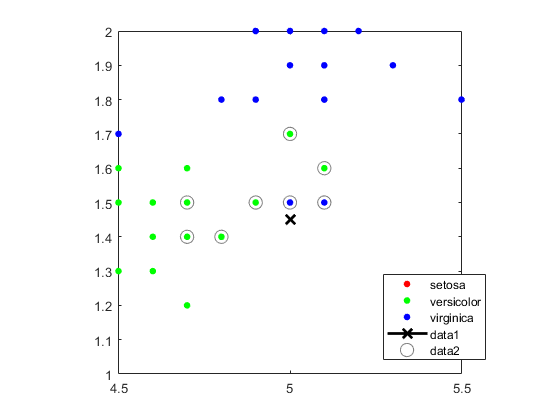

xlim([4.5 5.5]);
ylim([1 2]);
axis square

Find the species of the 10 neighbors.

tabulate(species(n))

Using a rule based on the majority vote of the 10 nearest neighbors, you can classify this new point as a versicolor.

Visually identify the neighbors by drawing a circle around the group of them. Define the center and diameter of a circle, based on the location of the new point.

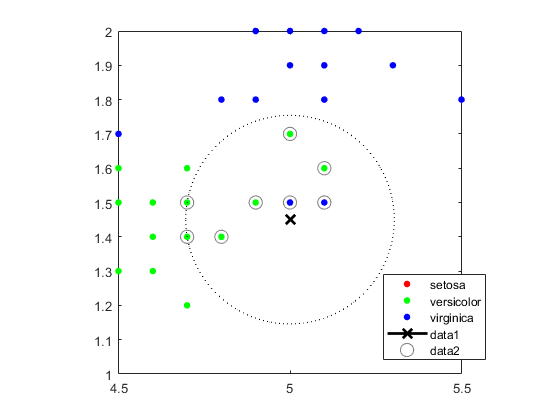

ctr = newpoint - d(end);
diameter = 2*d(end);
% Draw a circle around the 10 nearest neighbors.
h = rectangle('position',[ctr,diameter,diameter],...
   'curvature',[1 1]);

h.LineStyle = ':';

Using the same dataset, find the 10 nearest neighbors to three new points.

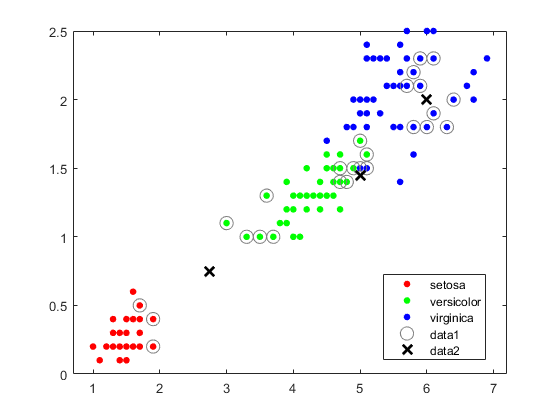

figure 
newpoint2 = [5 1.45;6 2;2.75 .75];
gscatter(x(:,1),x(:,2),species)
legend('location','best')
[n2,d2] = knnsearch(Mdl,newpoint2,'k',10);
line(x(n2,1),x(n2,2),'color',[.5 .5 .5],'marker','o',...
   'linestyle','none','markersize',10)
line(newpoint2(:,1),newpoint2(:,2),'marker','x','color','k',...
   'markersize',10,'linewidth',2,'linestyle','none')

Find the species of the 10 nearest neighbors for each new point.

tabulate(species(n2(1,:)))

       Value    Count   Percent
  versicolor        7     70.00%
      setosa        3     30.00%


tabulate(species(n2(2,:)))

tabulate(species(n2(3,:)))

For more examples using `knnsearch` methods and function, see the individual reference pages.

*Copyright 2012 The MathWorks, Inc.*

# Find Nearest Neighbors Using a Custom Distance Metric

This example shows how to find the indices of the three nearest observations in `X` to each observation in `Y` with respect to the chi-square distance. This distance metric is used in correspondence analysis, particularly in ecological applications.

Randomly generate normally distributed data into two matrices. The number of rows can vary, but the number of columns must be equal. This example uses 2-D data for plotting.

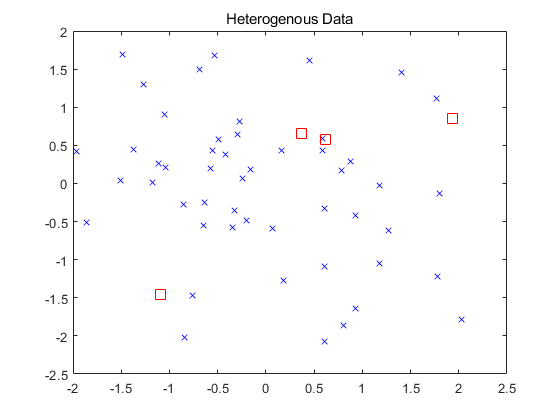

rng(1); % For reproducibility
X = randn(50,2);
Y = randn(4,2);

h = zeros(3,1);
figure;
h(1) = plot(X(:,1),X(:,2),'bx');
hold on;

h(2) = plot(Y(:,1),Y(:,2),'rs','MarkerSize',10);
title('Heterogenous Data')

The rows of `X` and `Y` correspond to observations, and the columns are, in general, dimensions (for example, predictors).

The chi-square distance between *j*-dimensional points *x* and *z* is 


$$\chi(x,z) = \sqrt{\displaystyle\sum^J_{j = 1}w_j\left(x_j - z_j\right)^2},$$


where $w_j$ is the weight associated with dimension *j*. 

Choose weights for each dimension, and specify the chi-square distance function. The distance function must:

- Take as input arguments one row of `X`, e.g., `x`, and the matrix `Z`.

- Compare `x` to each row of `Z`.

- Return a vector `D` of length $n_z$, where $n_z$ is the number of rows of `Z`. Each element of `D` is the distance between the observation corresponding to `x` and the observations corresponding to each row of `Z`.

w = [0.4; 0.6];
chiSqrDist = @(x,Z)sqrt((bsxfun(@minus,x,Z).^2)*w);

This example uses arbitrary weights for illustration.

Find the indices of the three nearest observations in `X` to each observation in `Y`.

k = 3;
[Idx,D] = knnsearch(X,Y,'Distance',chiSqrDist,'k',k);

`idx` and `D` are 4-by-3 matrices.

- `idx(j,1)` is the row index of the closest observation in `X` to observation *j* of `Y`, and `D(j,1)` is their distance.

- `idx(j,2)` is the row index of the next closest observation in `X` to observation *j* of `Y`, and `D(j,2)` is their distance.

- And so on.

Identify the nearest observations in the plot.

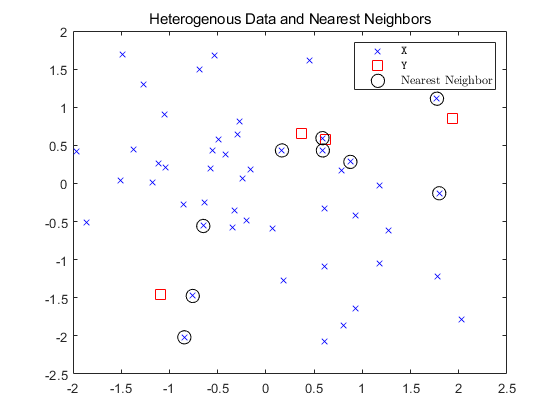

for j = 1:k
    h(3) = plot(X(Idx(:,j),1),X(Idx(:,j),2),'ko','MarkerSize',10);
end 
legend(h,{'\texttt{X}','\texttt{Y}','Nearest Neighbor'},'Interpreter','latex');
title('Heterogenous Data and Nearest Neighbors')
hold off;

Several observations of `Y` share nearest neighbors. 

Verify that the chi-square distance metric is equivalent to the Euclidean distance metric, but with an optional scaling parameter.

[IdxE,DE] = knnsearch(X,Y,'Distance','seuclidean','k',k,...
    'Scale',1./(sqrt(w)));
AreDiffIdx = sum(sum(Idx ~= IdxE))

AreDiffIdx =      0


AreDiffDist = sum(sum(abs(D - DE) > eps))

AreDiffDist =      0


The indices and distances between the two implementations of three nearest neighbors are practically equivalent.

*Copyright 2015 The MathWorks, Inc.*

# Construct KNN Classifier

This example shows how to construct a *k*-nearest neighbor classifier for the Fisher iris data.

Load the Fisher iris data.

load fisheriris
X = meas;    % Use all data for fitting
Y = species; % Response data

Construct the classifier using `fitcknn`.

Mdl = fitcknn(X,Y)

Mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'setosa'  'versicolor'  'virginica'}
           ScoreTransform: 'none'
          NumObservations: 150
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


A default *k*-nearest neighbor classifier uses a single nearest neighbor only. Often, a classifier is more robust with more neighbors than that.

Change the neighborhood size of `Mdl` to `4`, meaning that  `Mdl` classifies using the four nearest neighbors.

Mdl.NumNeighbors = 4;

*Copyright 2012 The MathWorks, Inc.*

# Examine Quality of KNN Classifier

This example shows how to examine the quality of a *k*-nearest neighbor classifier using resubstitution and cross validation.

Construct a KNN classifier for the Fisher iris data as in [Construct KNN Classifier](docid:stats_ug.btap7k2).

load fisheriris
X = meas;    
Y = species; 
rng(10); % For reproducibility
Mdl = fitcknn(X,Y,'NumNeighbors',4);

Examine the resubstitution loss, which, by default, is the fraction of misclassifications from the predictions of `Mdl`. (For nondefault cost, weights, or priors, see [loss](docid:stats_ug.bs85nh7).).

rloss = resubLoss(Mdl)

The classifier predicts incorrectly for 4% of the training data.

Construct a cross-validated classifier from the model.

CVMdl = crossval(Mdl);

Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

kloss = kfoldLoss(CVMdl)

The cross-validated classification accuracy resembles the resubstitution accuracy. Therefore, you can expect `Mdl` to misclassify approximately 4% of new data, assuming that the new data has about the same distribution as the training data.

*Copyright 2012 The MathWorks, Inc.*

# Predict Classification Using KNN Classifier

This example shows how to predict classification for a *k*-nearest neighbor classifier.

Construct a KNN classifier for the Fisher iris data as in [Construct KNN Classifier](docid:stats_ug.btap7k2).

load fisheriris
X = meas;    
Y = species; 
Mdl = fitcknn(X,Y,'NumNeighbors',4);

Predict the classification of an average flower.

flwr = mean(X); % an average flower
flwrClass = predict(Mdl,flwr)

*Copyright 2012 The MathWorks, Inc.*

# Modify KNN Classifier

This example shows how to modify a *k*-nearest neighbor classifier.

Construct a KNN classifier for the Fisher iris data as in [Construct KNN Classifier](docid:stats_ug.btap7k2).

load fisheriris
X = meas;    
Y = species; 
Mdl = fitcknn(X,Y,'NumNeighbors',4);

Modify the model to use the three nearest neighbors, rather than the default one nearest neighbor.

Mdl.NumNeighbors = 3;

Compare the resubstitution predictions and cross-validation loss with the new number of neighbors.

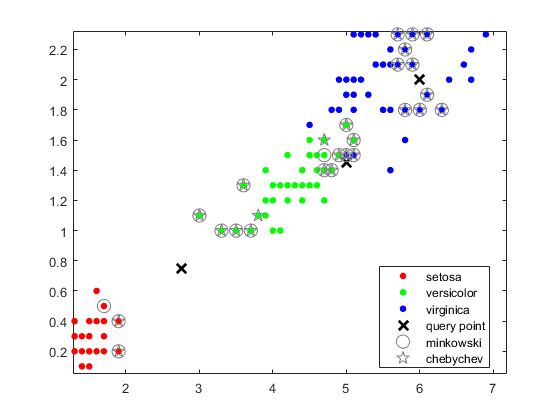

loss = resubLoss(Mdl)


rng(10); % For reproducibility
CVMdl = crossval(Mdl,'KFold',5);
kloss = kfoldLoss(CVMdl)

In this case, the model with three neighbors has the same cross-validated loss as the model with four neighbors (see [Examine Quality of KNN Classifier](docid:stats_ug.btap7l_)).

Modify the model to use cosine distance instead of the default, and examine the loss. To use cosine distance, you must recreate the model using the exhaustive search method.

CMdl = fitcknn(X,Y,'NSMethod','exhaustive','Distance','cosine');
CMdl.NumNeighbors = 3;
closs = resubLoss(CMdl)

The classifier now has lower resubstitution error than before.

Check the quality of a cross-validated version of the new model.

CVCMdl = crossval(CMdl);
kcloss = kfoldLoss(CVCMdl)

`CVCMdl` has a better cross-validated loss than `CVMdl`. However, in general, improving the resubstitution error does not necessarily produce a model with better test-sample predictions.

*Copyright 2012 The MathWorks, Inc.*

# Find *k*-Nearest Neighbors Using Different Distance Metrics

Find the 10 nearest neighbors in `X` to each point in `Y`, first using the Minkowski distance metric and then using the Chebychev distance metric.

Load Fisher's iris data set.

load fisheriris
X = meas(:,3:4);    % Measurements of original flowers
Y = [5 1.45;6 2;2.75 .75];  % New flower data

Perform a `knnsearch` between `X` and the query points `Y` using Minkowski and Chebychev distance metrics.

[mIdx,mD] = knnsearch(X,Y,'K',10,'Distance','minkowski','P',5);
[cIdx,cD] = knnsearch(X,Y,'K',10,'Distance','chebychev');

Visualize the results of the two nearest neighbor searches. Plot the training data. Plot the query points with the marker X. Use circles to denote the Minkowski nearest neighbors. Use pentagrams to denote the Chebychev nearest neighbors.

gscatter(X(:,1),X(:,2),species)
line(Y(:,1),Y(:,2),'Marker','x','Color','k',...
   'Markersize',10,'Linewidth',2,'Linestyle','none')
line(X(mIdx,1),X(mIdx,2),'Color',[.5 .5 .5],'Marker','o',...
   'Linestyle','none','Markersize',10)
line(X(cIdx,1),X(cIdx,2),'Color',[.5 .5 .5],'Marker','p',...
   'Linestyle','none','Markersize',10)
legend('setosa','versicolor','virginica','query point',...
'minkowski','chebychev','Location','best')

*Copyright 2015 The MathWorks, Inc.*